**Student Name:    _ _ _ _ _ _ _ _ _ _ _ _ _ **

**H-ID:                    _ _ _ _ _ _ _ _ _ _ _ _ _ **

# **Step Response Analysis of a Second Order System**

Open loop transfer function;


$$G(s) = \frac{100}{s^2 + 15s }$$


- plot of step response

- transient characteristics of the response

clc;
clear;
close all;

## Defining Inputs / variables

% define gain, K variable
K = [1 10 100]

K =      1    10   100


% define the variable 's' for the transfer function   
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


## Open Loop System

- Create the open loop transfer function & plot the step response

- also get transient charateristics of the response using [`stepinfo(sys)`](https://www.mathworks.com/help/releases/R2020a/control/ref/stepinfo.html)

Plot title must also include your name & H-ID and axes labels.

% define the transfer function below and save it in 'op_l'
op_l = 100 / (s^2 + 15*s)

op_l =
 
     100
  ----------
  s^2 + 15 s
 
Continuous-time transfer function.
Model Properties


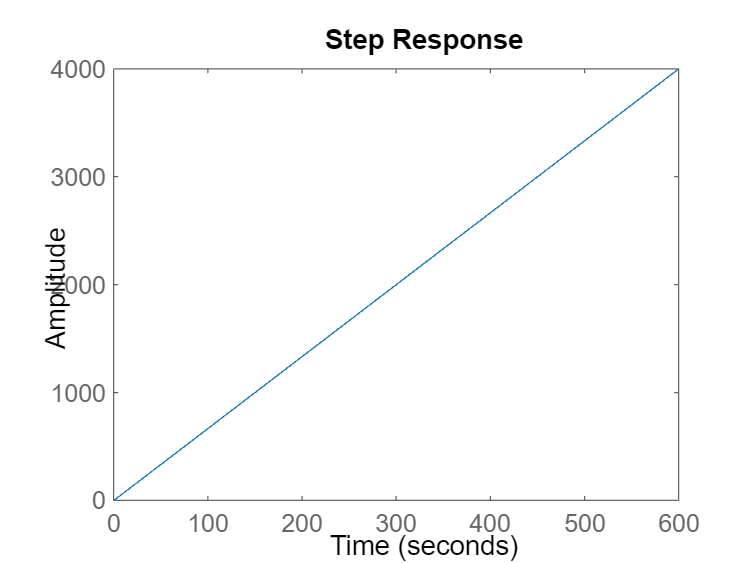


% plot the step response - add proper titles 
step(op_l)


% determine the transient characteristics of the open loop system
stepinfo(op_l)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


## Closed Loop System

- Add the gain the close loop system and investigate its effect on the system response

Plot title must also include your name & H-ID and axes labels.

**Hint:**

`sys = `[`feedback`](https://www.mathworks.com/help/releases/R2020a/control/ref/feedback.html)`(sys1,sys2)` returns a model object `sys` for the negative feedback interconnection of model objects `sys1,sys2`.

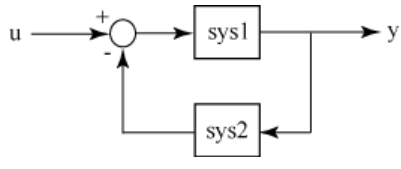

% generate the transfer function of close loop system with given feedback
% having gain K =1
% and save in a variable "cl_1"
cl_1 = feedback(K(1)*op_l, 1)

cl_1 =
 
        100
  ----------------
  s^2 + 15 s + 100
 
Continuous-time transfer function.
Model Properties


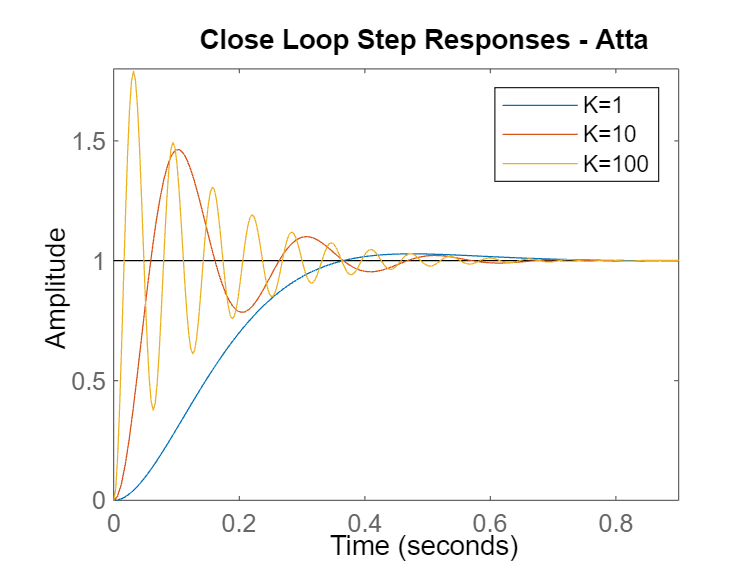


% use step function to generate the step response of close loop system
% having gain K = 1
step(cl_1);
hold on;

% generate the transfer function of close loop system with given feedback
% having gain K =10
% and save in a variable "cl_10"
cl_10 = feedback(K(2)*op_l, 1);

% use step function to generate the step response of close loop system
% having gain K = 10
step(cl_10)


% generate the transfer function of close loop system with given feedback
% having gain K =100
% and save in a variable "cl_100"
cl_100 = feedback(K(3)*op_l, 1);

% use step function to generate the step response of close loop system
% having gain K = 100
step(cl_100)
hold off;
% add title & legends to the plot
title('Close Loop Step Responses - Atta');
legend('K=1', 'K=10', 'K=100')

% transient response of the all close loop systems
stepinfo(cl_1)

ans = struct with fields:
         RiseTime: 0.2288
    TransientTime: 0.5743
     SettlingTime: 0.5743
      SettlingMin: 0.9049
      SettlingMax: 1.0284
        Overshoot: 2.8369
       Undershoot: 0
             Peak: 1.0284
         PeakTime: 0.4728


damp(cl_1)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.50e+00 + 6.61e+00i     7.50e-01       1.00e+01         1.33e-01    
 -7.50e+00 - 6.61e+00i     7.50e-01       1.00e+01         1.33e-01    


## Don't forget

- to put your name at the beginning of the Live Script

- to save the Live Script to store the output

- to save the Live Script file as PDF